# **LQR simulation**

**author: Xin Lyu**

clear all;
close all;
% Define parameteres and states

m = 1; % kg
k = 1 ;% N/m
b = 0.5; % Ns/m

xd = [0;0];
% define weighted matrix
Q = eye(2);
R = 0.1;

A = [0,1;-1,-0.5]

A =          0    1.0000
   -1.0000   -0.5000


B = [0;1]

B =      0
     1


C = [0,0];
D = 0;
n = size(A,1);
p = size(B,2);
Ts= 0.1

Ts = 0.1000

sym_d = c2d(ss(A,B,C,D),Ts);
A_d = sym_d.A;
B_d = sym_d.B;

% intialize state
x0 = [1;0];
x = x0;
u0 = 2;
u = u0;

% define system steps
k_steps = 100;
x_history = zeros(n,k_steps);
x_history(:,1) = x;

u_history = zeros(p,k_steps);
u_history(:,1) = u;
P_k = Q;
% calcualte F 
for k=1:k_steps
    F = inv(R+B_d'*P_k*B_d)*B_d'*P_k*A_d;
    P_k = (A_d-B_d*F)'*P_k*(A_d-B_d*F)+(F)'*R*F+Q;

    if k == 1;
        F_N = F;
    else
        F_N = [F;F_N];
    end

end

% simulation
for k =1:k_steps
    %calculate u
    u = -F_N(k,:)*x;
    x = A_d*x+B_d*u;
    x_history(:,k+1) = x;
    u_history(:,k) = u;
end
subplot(2,1,1);
for i=1:n
    plot(x_history(i,:));
    hold;
end

Current plot held
Current plot released


legend('x1','x2');
xlim([1,k_steps]);
grid on

subplot(2,1,2);
for i = 1:p
    stairs (u_history(i,:));
    hold;
end

Current plot held


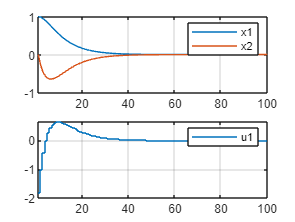

legend('u1');
xlim([1,k_steps]);
grid on